% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------

%ex3.1.1 找稳态点，求解非线性方程就可以了，所以使用了fsolve
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
F1=300;
F2=300;
F3=250;
F4=250;
us = [F1;F2]; % [cm3/s] Flow rates
ds = [F3;F4]; % [cm3/s] Flow rates
xs0 = [5000; 5000; 5000; 5000]; % [g] Initial guess on xs
xs = fsolve(@ModifiedFourTankSystemWrap,xs0,[],us,ds,p)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    4.1068
    3.6822
    2.3787
    2.2157


ys = FourTankSystemSensor(xs,p)

ys =   108.0357
   96.8675
   62.5759
   58.2863


zs = FourTankSystemOutput(xs,p)

zs =   108.0357
   96.8675


%ex3.4.1 对非线性系统进行线性化，需要使用雅可比矩阵求导
syms x1 x2 x3 x4 u1 u2 d1 d2
m = [x1;x2;x3;x4]; % Mass of liquid in each tank [g]
F = [u1;u2;d1;d2]; % Flow rates in pumps [cm3/s]
a = p(1:4,1); % Pipe cross sectional areas [cm2]
A = p(5:8,1); % Tank cross sectional areas [cm2]
gamma = p(9:10,1); % Valve positions [-]
g = p(11,1); % Acceleration of gravity [cm/s2]
rho = p(12,1); % Density of water [g/cm3]

% Inflows

qin(1,1) = gamma(1)*F(1); % Inflow from valve 1 to tank 1 [cm3/s]
qin(2,1) = gamma(2)*F(2); % Inflow from valve 2 to tank 2 [cm3/s]
qin(3,1) = (1-gamma(2))*F(2); % Inflow from valve 2 to tank 3 [cm3/s]
qin(4,1) = (1-gamma(1))*F(1); % Inflow from valve 1 to tank 4 [cm3/s]
% Out_finallows
h = m./(rho*A); % Liquid level in each tank [cm]
qout = a.*sqrt(2*g*h); % Out_finallow from each tank [cm3/s]
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1))+F(3); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1))+F(4); % Mass balance Tank 4
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F],[xs;us;ds]),4))

Ass =    -0.0069         0    0.0090         0
         0   -0.0073         0    0.0094
         0         0   -0.0090         0
         0         0         0   -0.0094


Bss=eval(vpa(subs(jacobian(fx,F(1:2)),[m;F],[xs;us;ds]),4))

Bss =     0.4500         0
         0    0.4000
         0    0.6000
    0.5500         0


Bdss=eval(vpa(subs(jacobian(fx,F(3:4)),[m;F],[xs;us;ds]),4))

Bdss =      0     0
     0     0
     1     0
     0     1


Css=eval(vpa(subs(jacobian(gx,m),[m;F],[xs;us;ds]),4))

Css =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Czss=Css(1:2,:)

Czss =     0.0026         0         0         0
         0    0.0026         0         0


Dss=eval(vpa(subs(jacobian(gx,F(1:2)),[m;F],[xs;us;ds]),4))

Dss =      0     0
     0     0
     0     0
     0     0


Dzss=Dss(1:2,:)

Dzss =      0     0
     0     0


%ex3.5 线性系统的离散化
Ts = 4; 
[Ad,Bd]=c2dzoh(Ass,Bss,Ts)

Ad =     0.9729         0    0.0350         0
         0    0.9714         0    0.0362
         0         0    0.9645         0
         0         0         0    0.9632


Bd =     1.7755    0.0425
    0.0403    1.5770
         0    2.3571
    2.1593         0


[Ad,Bd_d]=c2dzoh(Ass,Bdss,Ts)

Ad =     0.9729         0    0.0350         0
         0    0.9714         0    0.0362
         0         0    0.9645         0
         0         0         0    0.9632


Bd_d =     0.0708         0
         0    0.0733
    3.9286         0
         0    3.9260


%无约束线性MPC算法设计，考虑前馈（扰动）和输入的变化率
%soft output constriant
%因为水箱有4个，我们想要控制的有2个，但我们的约束是加到四个水箱上，所以这里需要改变矩阵结构
%如果我们想要加入松弛变量，那么松弛变量也需要放入待求矩阵，矩阵需要进一步扩大
N=5;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
num_eta=num_y;
U=[1;1];
X0=[1;1;1;1];
D=ones(N*num_d,1);
u_min=0;
u_max=500;
u_delta_min=-2;
u_delta_max=2;
z_min=0;
z_max=500;
num_u_delta_cons=N*num_u;
num_z_cons=N*num_y;
%Phi矩阵只与x0有关，表示的z是不变的，所以phi的维度不变
Phi=zeros(N*num_y,num_x);%[CA]*x0 ->>> y #####[num_y*N,num_x]
%Gam矩阵需要改变，因为我们的自变量变为[U;Eta]
Gam=zeros(N*num_y,N*num_u+N*num_eta);%[H]*Uk ->>> y
%Gam_d无需改变
Gam_d=zeros(N*num_y,N*num_d);%[Hd]*Dk ->>> y

%预测值与参考值误差的权重矩阵Qz,海森矩阵Hr,一阶梯度Mr
%Qz不需要改变，权重矩阵是指的是z的权重
Qz=diag(zeros(N*num_y,1));
%input rate的权重矩阵S,海森矩阵Hs,一阶梯度Mu_delta
Sz=diag(ones(num_u,1));
%input rate 的矩阵需要拉长
Hs=zeros(N*num_u+N*num_eta,N*num_u+N*num_eta);
%Mu_delta就是input rate的g
Mu_delta=zeros(N*num_u+N*num_eta,num_u);
Mu_delta(1:num_u,:)=-Sz;
%松弛变量eta的权值,g需要？
He=diag([zeros(N*num_u,1);ones(N*num_eta,1)]);

U0=zeros(N*num_u+N*num_eta,1);
Iu=diag(ones(num_u,1));
%所有的不等式条件都需要重新构造
Au_delta_cons=zeros(num_u_delta_cons,N*num_u+N*num_eta);
%eta在价值函数中的H_eta
H_eta=diag(ones(N*num_eta,1));
for i=1:N
    %fill the Phi
    Phi((i-1)*num_y+1:i*num_y,:)=Css*Ad^i;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %fill the Gam
    Gam_i=zeros(num_y,N*num_u+N*num_eta);%[num_x * num_u*N]
    for j=1:i
        Gam_i(:,(j-1)*num_u+1:j*num_u)=Css*(Ad^(i-j))*Bd;%[Hn,Hn-1,Hn-2]
    end
    Gam((i-1)*num_y+1:i*num_y,:)=Gam_i;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %fill the Gam_d
    Gam_di=zeros(num_y,N*num_d);%[num_x * num_u*N]
    for j=1:i
        Gam_di(:,(j-1)*num_d+1:j*num_d)=Css*(Ad^(i-j))*Bd_d;%[Hn,Hn-1,Hn-2]
    end
    Gam_d((i-1)*num_y+1:i*num_y,:)=Gam_di;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %fill the Qz
    qz=diag([ones(num_z,1);zeros(num_y-num_z,1)]);
    Qz((i-1)*num_y+1:i*num_y,(i-1)*num_y+1:i*num_y)=qz;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %fill the Hs
    if i==1
        Hs(1:num_u,1:2*num_u)=[2*Sz,-Sz];
    elseif i==N
        Hs((i-1)*num_u+1:(i)*num_u,(i-2)*num_u+1:i*num_u)=[-Sz,Sz];
    else
        Hs((i-1)*num_u+1:(i)*num_u,(i-2)*num_u+1:(i+1)*num_u)=[-Sz,2*Sz,-Sz];
    end
    %fill the U0
    U0((i-1)*num_u+1:i*num_u,:)=U;
    %fill the Au_delta_cons
    if i==1
        Au_delta_cons(1:num_u,1:num_u)=Iu;
    else
        Au_delta_cons((i-1)*num_u+1:(i)*num_u,(i-2)*num_u+1:i*num_u)=[-Iu,Iu];
    end
end
%初始状态值的一阶梯度Mx0, 干扰项的一阶梯度Md
%预测值与参考值误差的一阶梯度Mr
%input rate的一阶梯度Mu_delta
%g=Mx0*x0+Mr*ref+Ms
Mx0=Gam'*Qz*Phi;
Md=Gam'*Qz*Gam_d;
Mr=-Gam'*Qz;
Hr=Gam'*Qz*Gam;
Hu=Hr+Hs;

H_all =     2.0001    0.0000   -0.9999    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000    2.0001    0.0000   -0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

%Lx0=-Hu\Mx0;
%Lr=-Hu\Mr;
%Lu_delta=-Hu\Mu_delta;
%Ld=-Hu\Md;
%Kx0=Lx0(1:num_u,:)
%Kr=Lr(1:num_u,:)
%Ku_delta=Lu_delta(1:num_u,:)
%Kd=Ld(1:num_u,:)
%z的不等式矩阵
Az_cons_min=Gam;
Az_cons_min(:,N*num_u+1:end)=diag(1*ones(N*num_eta,1));
Az_cons_max=Gam;
Az_cons_max(:,N*num_u+1:end)=diag(-1*ones(N*num_eta,1));
Z_min=z_min*ones(num_z_cons,1)-Phi*X0-Gam_d*D;
Z_max_fake=5000*ones(num_z_cons,1);
Z_max=z_max*ones(num_z_cons,1)-Phi*X0-Gam_d*D;
Z_min_fake=zeros(num_z_cons,1);
%加上eta>=0
U_min=[u_min*ones(N*num_u,1);zeros(N*num_eta,1)];
U_max=[u_max*ones(N*num_u,1);5000*ones(N*num_eta,1)];%eta上限给个很大的值就可以
U_delta_min=u_delta_min*ones(num_u_delta_cons,1);
U_delta_max=u_delta_max*ones(num_u_delta_cons,1);
U_delta_min(1)=u_delta_min+U(1);
U_delta_min(2)=u_delta_min+U(2);
U_delta_max(1)=u_delta_max+U(1);
U_delta_max(2)=u_delta_max+U(2);

A_ieq=[Au_delta_cons;Az_cons_min;Az_cons_max];
b_ieq_min=[U_delta_min;Z_min;Z_min_fake];
b_ieq_max=[U_delta_max;Z_max_fake;Z_max];
%u_new=Kx0*Y+Kr*R+Ku_delta*U+Kd*D;

%%有约束线性MPC算法设计，考虑前馈（扰动）和输入的变化率,真正体现MPC的优势的地方在于对约束的处理
%有约束意味着没有解析解（如果是硬约束）
%对input进行约束，input本身和其变化率
%对output进行软约束
%闭环测试线性MPC，对线性离散系统
t0 = 0.0; % [s] Initial time
t_final = 2000; % [s] Final time
Ts = 4; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
N_pre=10;
u_min=0;
u_max=300;
z_min=0;
z_max=150;
u_delta_min=-2;
u_delta_max=2;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x0=zeros(4,1);
x(:,1) = x0;
xk=x0;
rk=100*ones(N_pre*num_y,1);%z1,z2 ref
dk=ones(N_pre*num_d,1);%d1,d2 ref
uk=zeros(num_u,1);%d1,d2 ref
for k = 1:N-1
yk=Css*xk; % Sensor function
zk=Czss*xk; % Output function
%uk=MPCcompute_linear(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_qp_analytical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_inputCons_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre);
uk=MPCcompute_linear_inputCons_outputSoftCons_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre);
xk=Ad*xk+Bd*uk+Bd_d*dk(1:num_d);
x(:,k+1)=xk;
y(:,k+1)=yk;
z(:,k+1)=zk;
u(:,k+1)=uk;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because the objective function

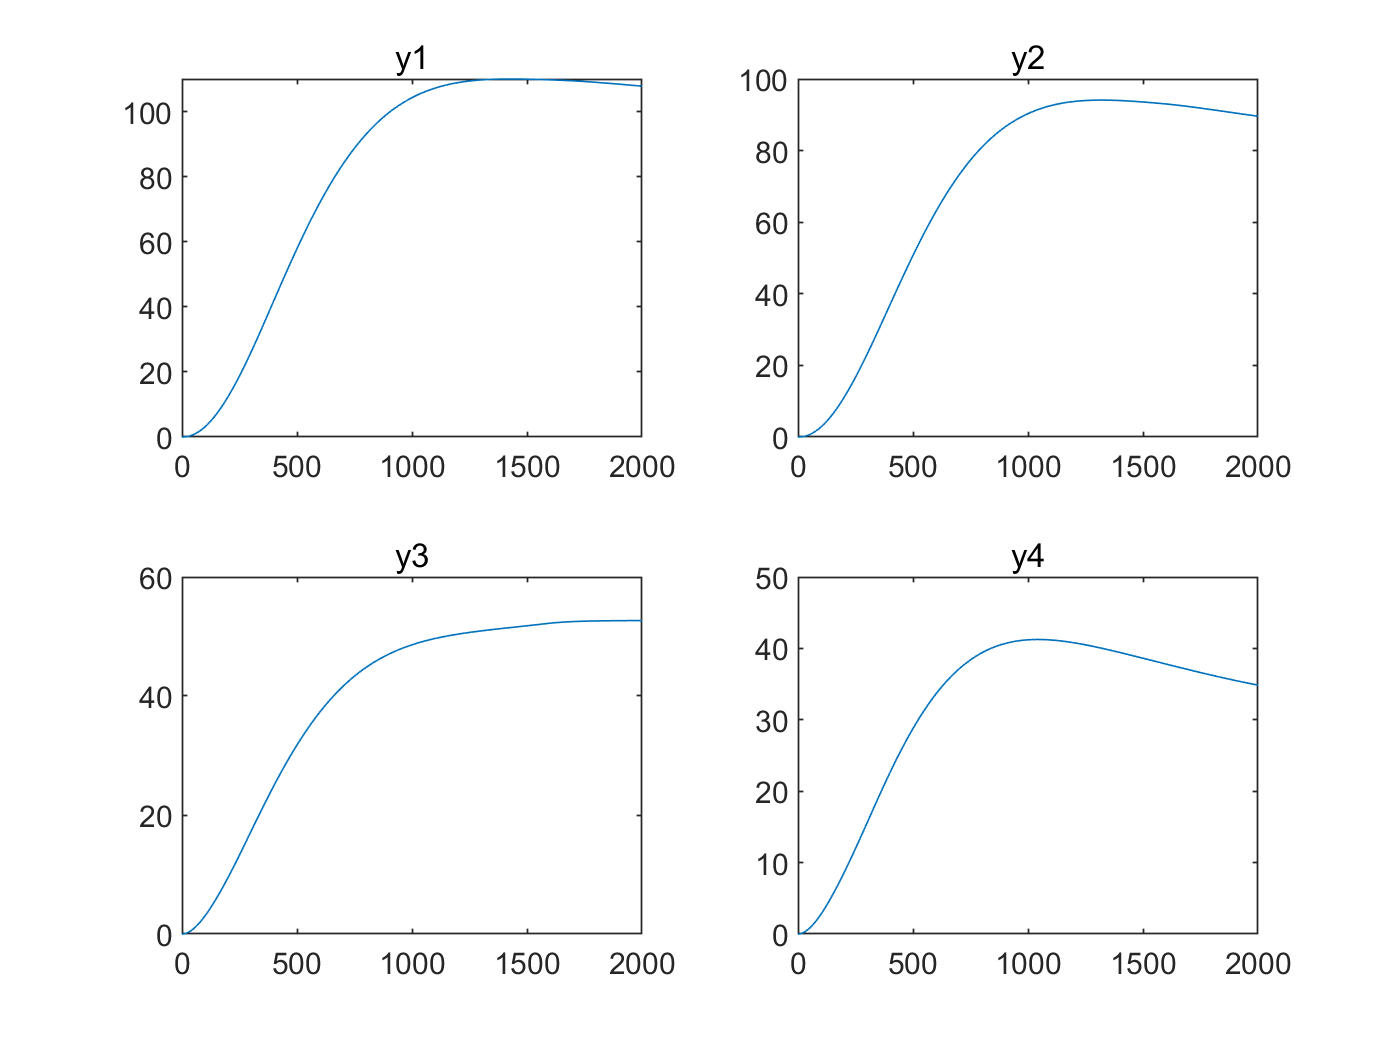

figure
subplot(2,2,1)
plot(t,y(1,:))
title('y1')
subplot(2,2,2)
plot(t,y(2,:))
title('y2')
subplot(2,2,3)
plot(t,y(3,:))
title('y3')
subplot(2,2,4)
plot(t,y(4,:))
title('y4')

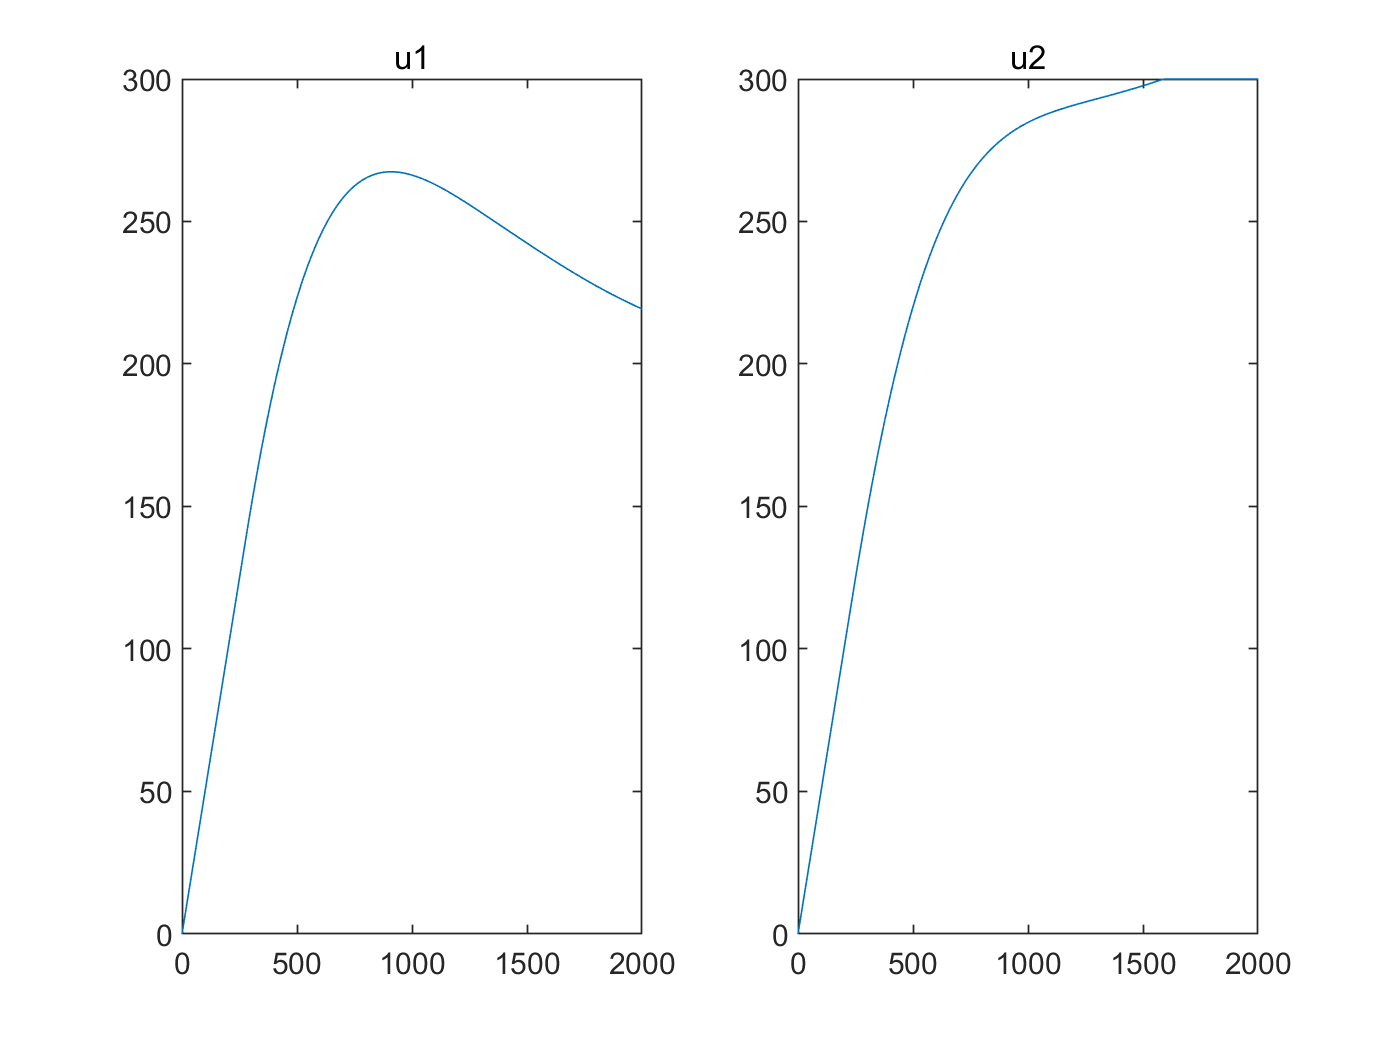

figure;
subplot(1,2,1)
plot(t,u(1,:))
title('u1')
subplot(1,2,2)
plot(t,u(2,:))
title('u2')